clear, clc, clf, close all;

## 加载原始数据

raw_record = importdata('data\excit\No0_excitation_trajectory_parameters_0-0-0-0-0-0-0.csv');

addpath '..\excitation\utils';
PERIOD = 0.001;

torque_record = raw_record.data(:, 2 : 8);
point_record = raw_record.data(:, 9 : 15);
speed_record = raw_record.data(:, 16 : 22);

% order of filter
n = 5;
% sampling frequency 
ws = 1000;
% cut-off frequency
wc = 5;
% number of sampling points
pnt = 20000;

## 关节位置滤波

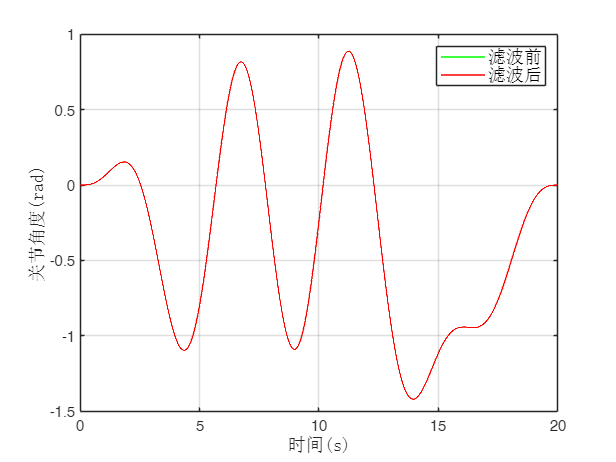

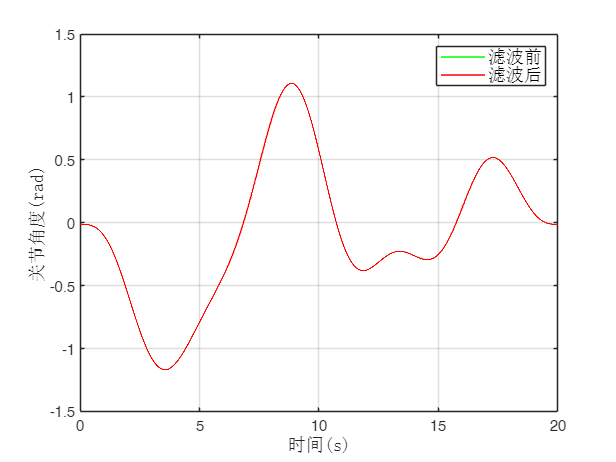

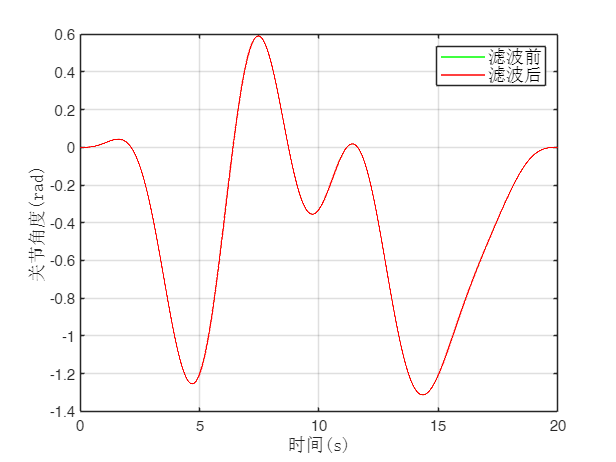

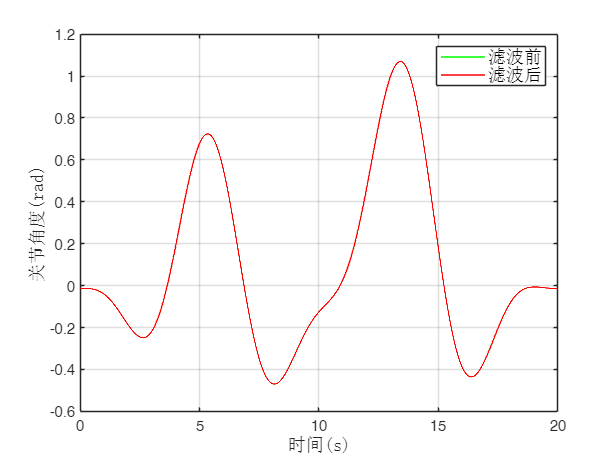

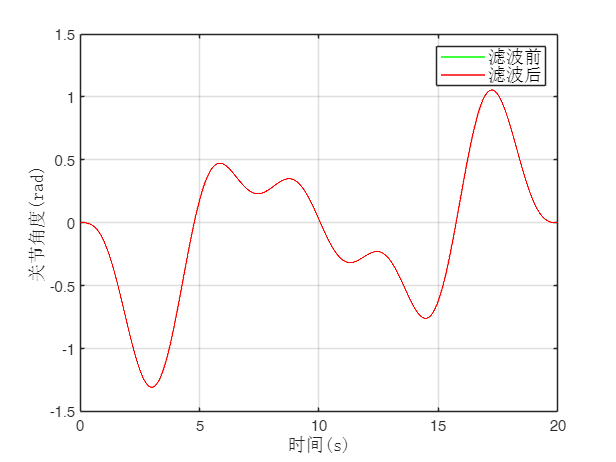

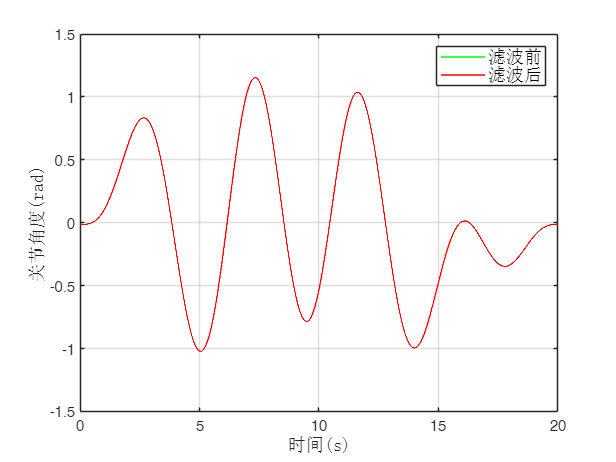

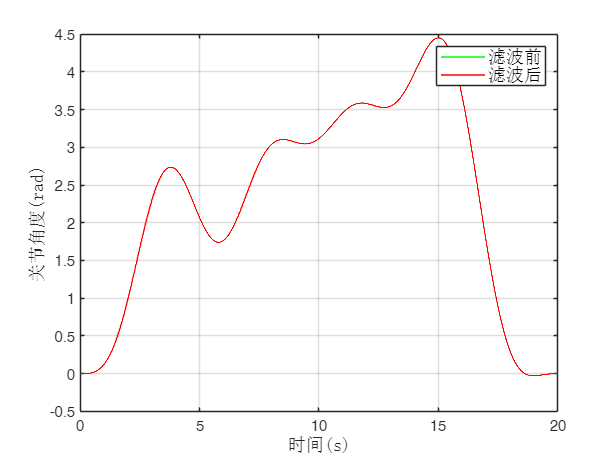

q_filt = ang_filter(n, ws, wc, point_record, '.\figs\excit\ang\');

## 关节速度滤波

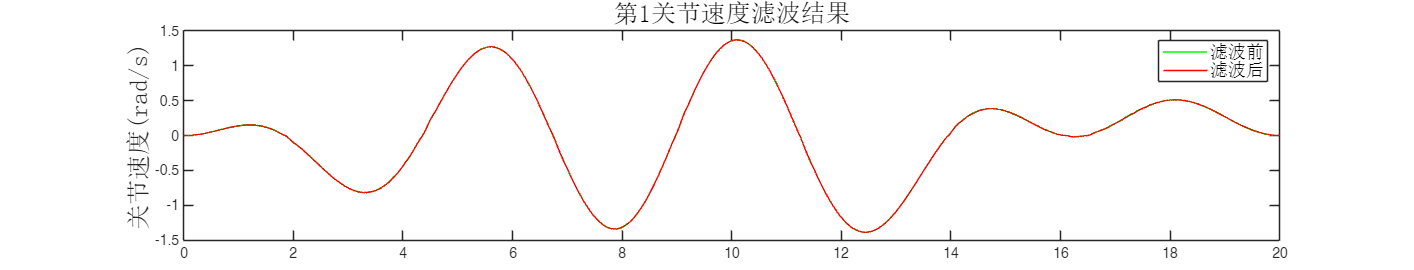

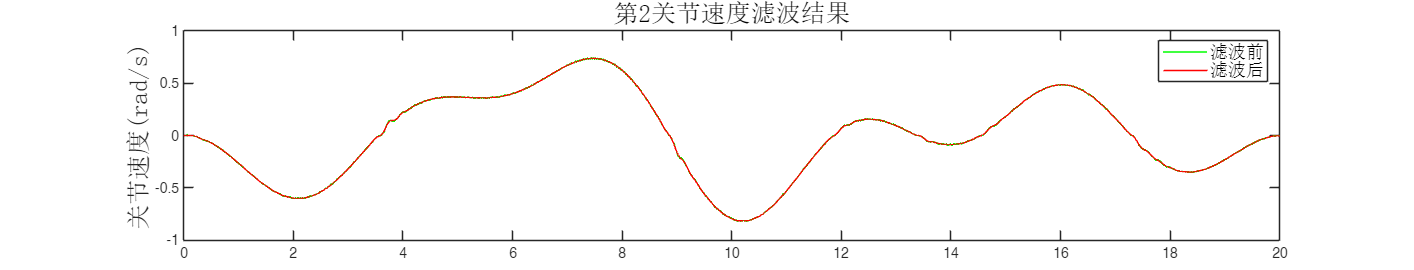

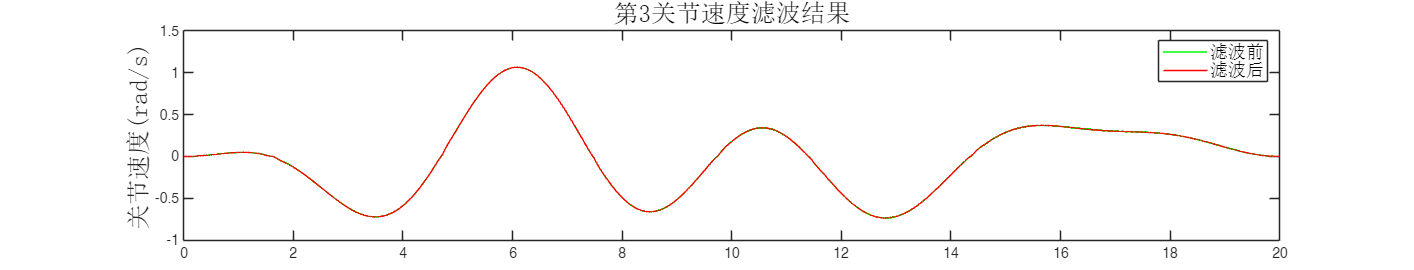

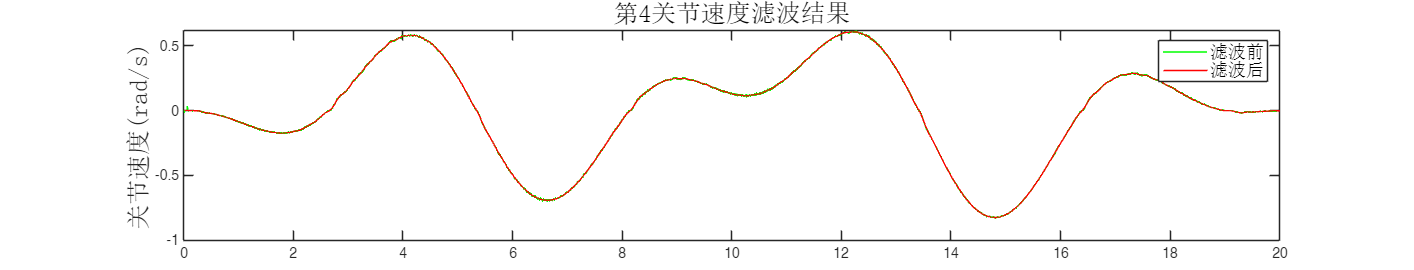

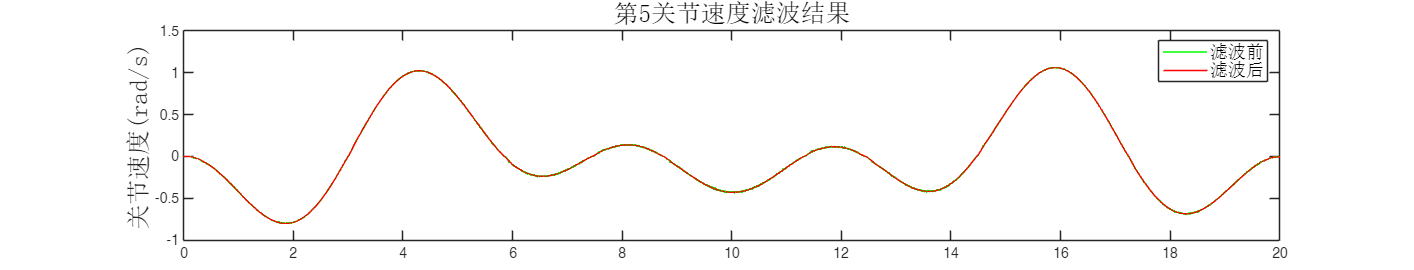

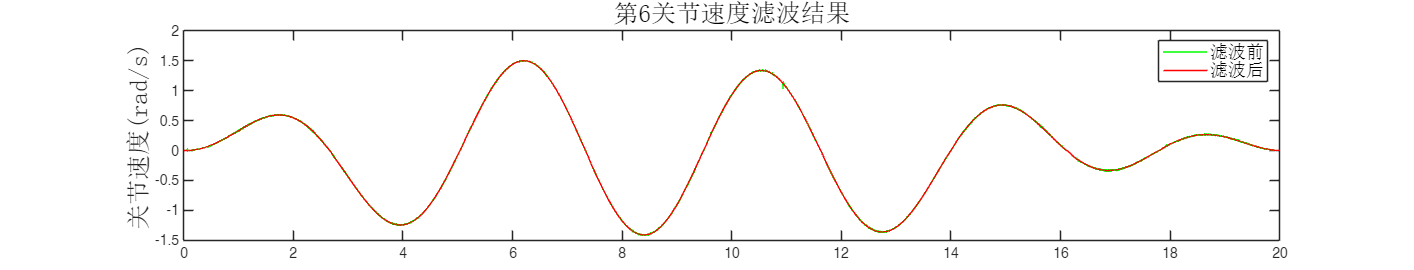

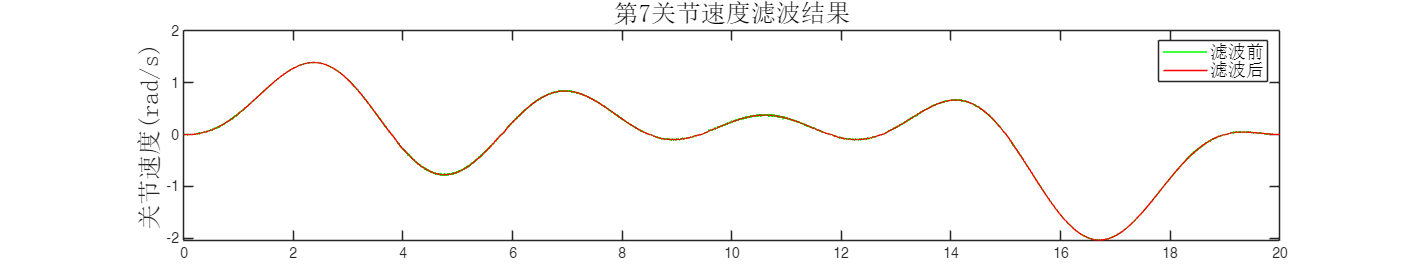

qd_filt = vel_filter(n, ws, wc, speed_record, 'sensor', '.\figs\excit\vel\'); 

## 力矩滤波结果

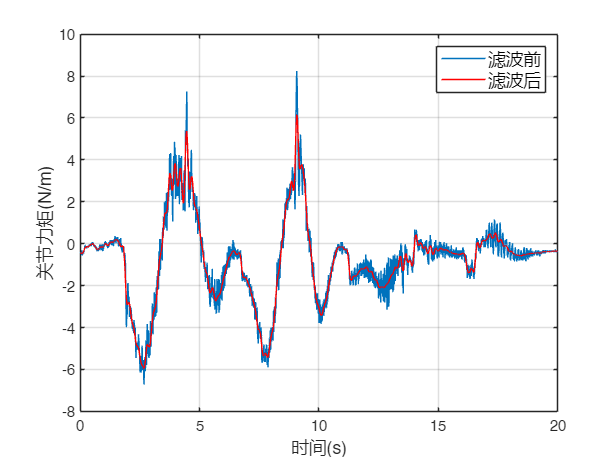

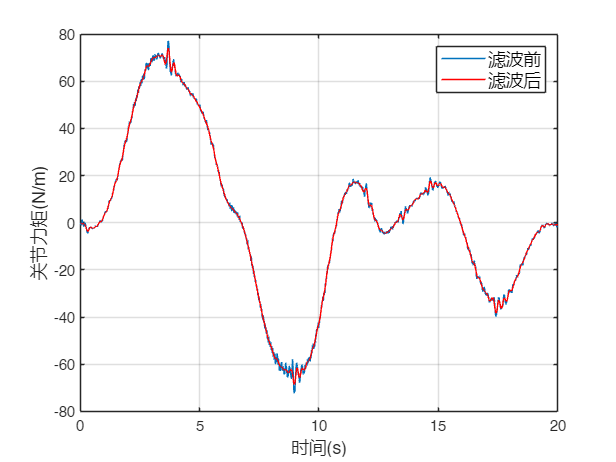

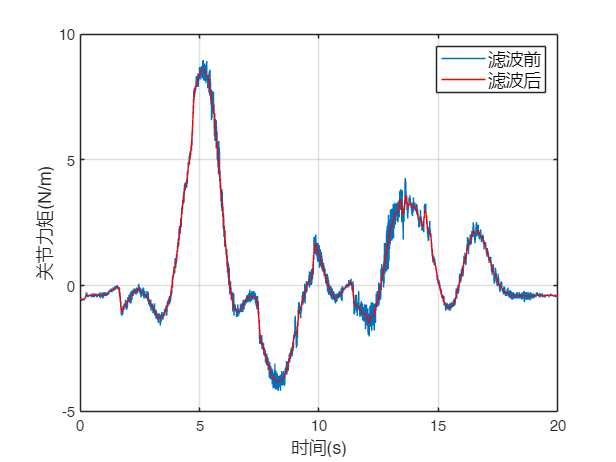

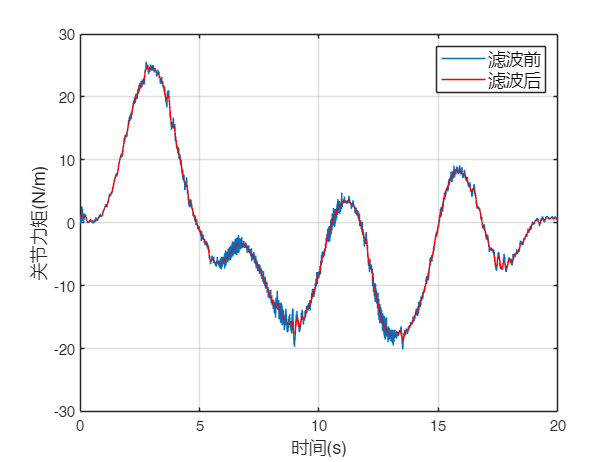

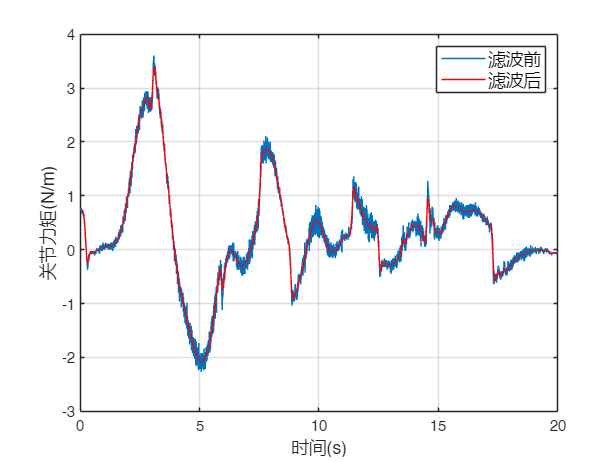

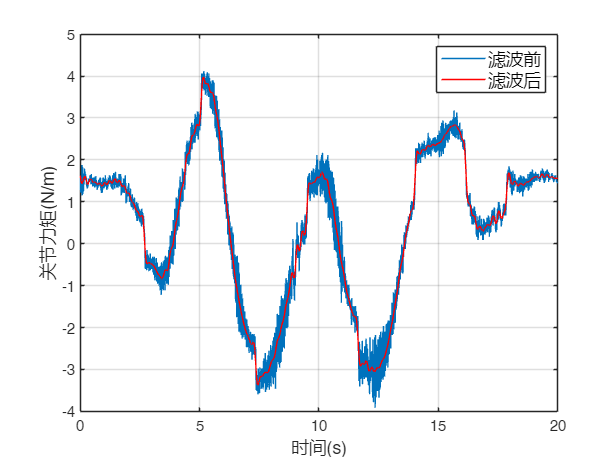

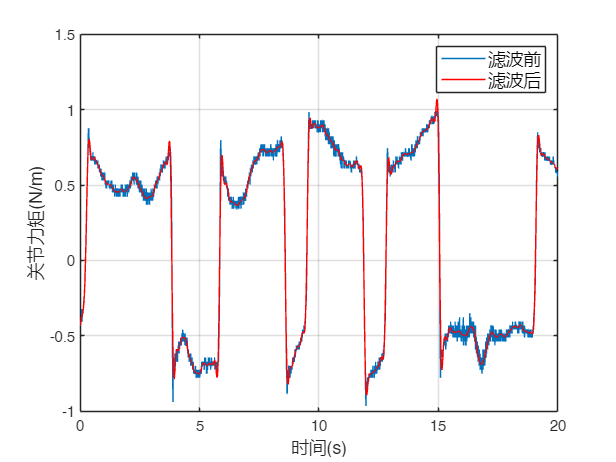

t_filt = trq_filter(n, ws, wc, torque_record, '.\figs\excit\trq\');

## 处理加速度

qdd_computed = zeros(size(qd_filt));
for i = 1 : 7
    qdd_computed(1, i) = qd_filt(1, i) * ws;
    qdd_computed(2 : end, i) = diff(qd_filt(:, i)) * ws;
end

## 加速度滤波

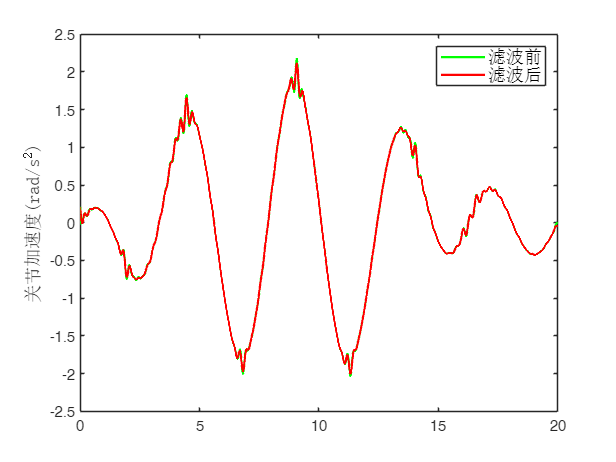

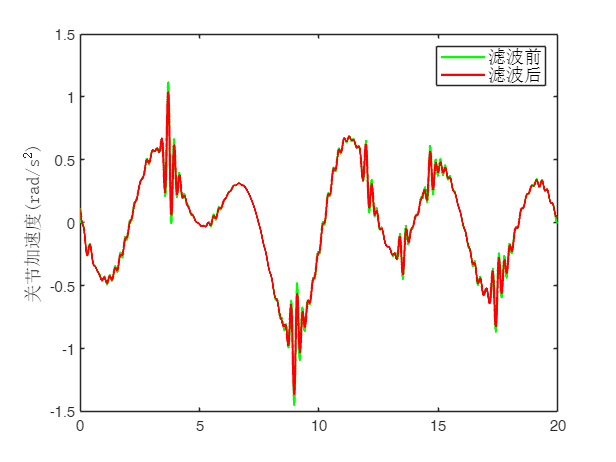

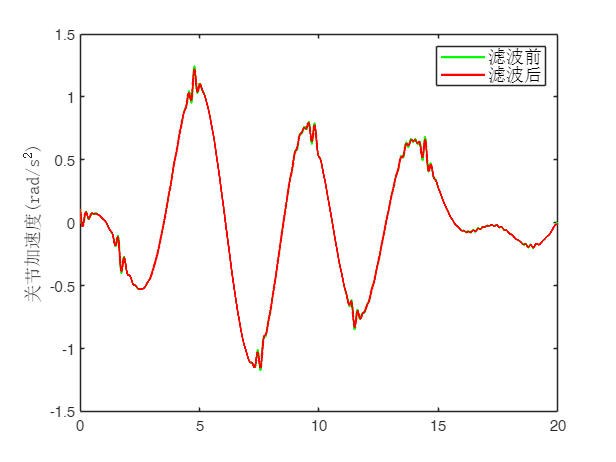

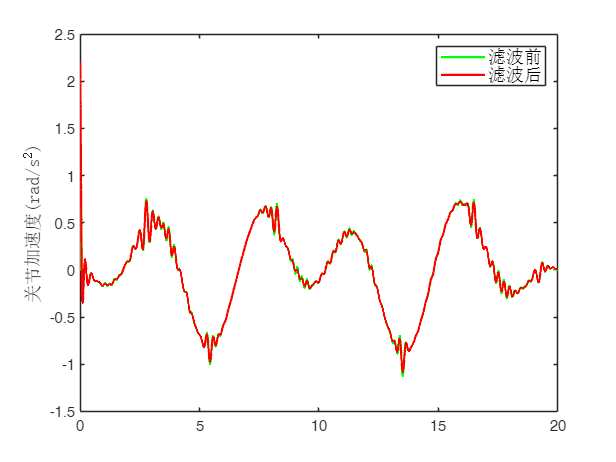

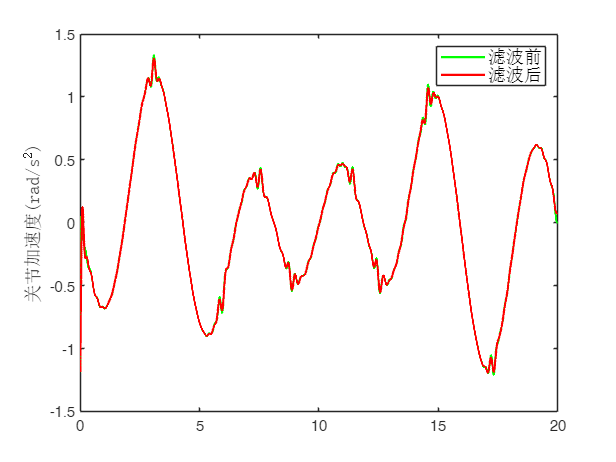

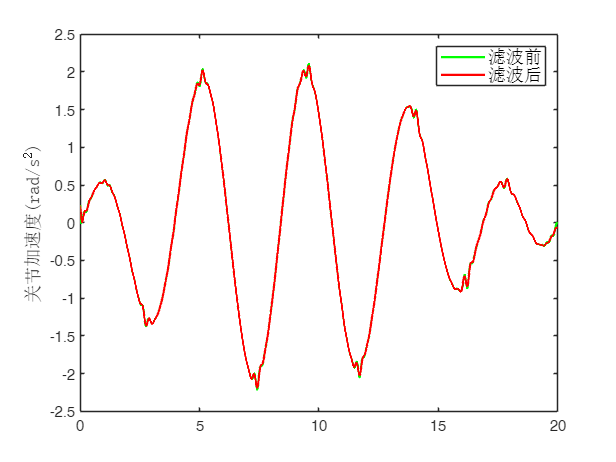

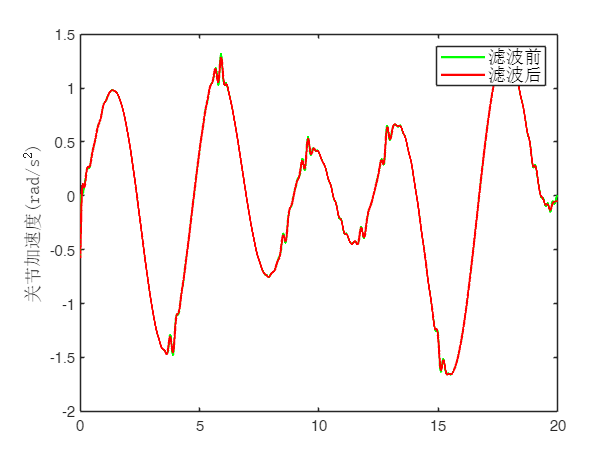

qdd_filt = acc_filter(n, ws, wc, qdd_computed, 'sensor', '.\figs\excit\trq\');

## 保存结果

save('..\identify\data\filted_No2_excitation_trajectory.mat');